# Explore Air Quality Data and Synchronize

Use the subsets of data first in exploring the data imported in `AccessMeteorologicalData.mlx`, then scale to synchronize all data to daily timestamps by location.

Load the subsets of data and note the environment.

useSpark = false;
load sampleData

head(subset_O)

ans = 8×8 timetable
         DateLocal          ParameterName    ArithmeticMean    AQI    SiteNum    StateName     CountyName     Latitude    Longitude
    ____________________    _____________    ______________    ___    _______    __________    ___________    ________    _________
    06-May-1993 00:00:00        Ozone           0.029208       36     "6001"     California    Kern            35.504      -119.27 
    09-Jun-2002 00:00:00        Ozone           0.031792       38     "3002"     Florida       Manatee         27.633      -82.546 
    23-Feb-1994 00:00:00        Ozone           0.014333       22     "0003"     California    

head(subset_T)

ans = 8×8 timetable
         DateLocal          SiteNum    SampleMeasurement       ParameterName        StateName      CountyName      Latitude    Longitude    hh
    ____________________    _______    _________________    ___________________    ___________    _____________    ________    _________    __
    28-Sep-2002 18:00:00    "0003"            64            Outdoor Temperature    Michigan       Allegan           42.768      -86.149     18
    03-Jun-1995 23:00:00    "1021"            54            Outdoor Temperature    California     Santa Barbara     34.403      -119.46     23
    13-Feb-2014 06:00:00    "0003"            10   

There are many ways to explore the data. Use the `summary` function for a quick look at a few variables and the timestamps.

s_T = summary(temps1);
s_O = summary(ozone1)

s_O = struct with fields:
         DateLocal: [1×1 struct]
     ParameterName: [1×1 struct]
    ArithmeticMean: [1×1 struct]
               AQI: [1×1 struct]
           SiteNum: [1×1 struct]
         StateName: [1×1 struct]
        CountyName: [1×1 struct]
          Latitude: [1×1 struct]
         Longitude: [1×1 struct]

Examine the timestamps in the recent (sequential) data to explore the granularity (hourly, daily) of the measurements.

s_T.DateLocal

ans = struct with fields:
          Size: [50000 1]
          Type: 'datetime'
           Min: 01-Jan-2017 00:00:00
        Median: 29-Jul-2017 20:00:00
           Max: 31-Dec-2017 23:00:00
    NumMissing: 0
      TimeStep: NaN

s_O.DateLocal

ans = struct with fields:
          Size: [50000 1]
          Type: 'datetime'
           Min: 2017-01-01
        Median: 2017-07-02
           Max: 2017-12-31
    NumMissing: 0
      TimeStep: NaN

The TimeStep is `NaN` since the data are non-regular (monotonically increasing). There are repeated timetamps since there are multiple locations for one data set. 

## Examine data by location

We want to synchronize the data based on the location. Each state and county have unique site numbers. Since the site numbers repeat, we must consider all three together or group by a larger location. In this case, we'll group by the state to build our model. Expore the locations represented in the subset by visualization. 

Visualize this info on a map by latitude and longitude.

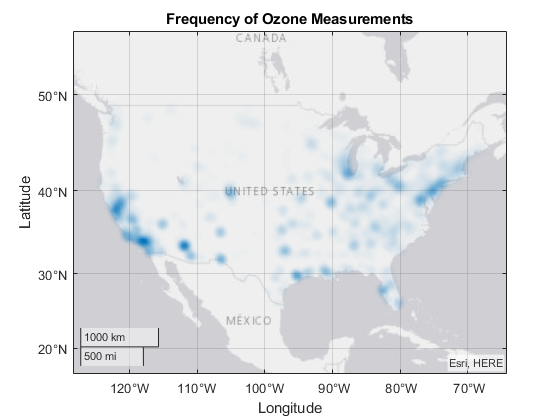

geodensityplot(subset_O.Latitude,subset_O.Longitude);
title("Frequency of Ozone Measurements")

geolimits([16.4 55.7],[-128.4 -64.2])  % zoom in 

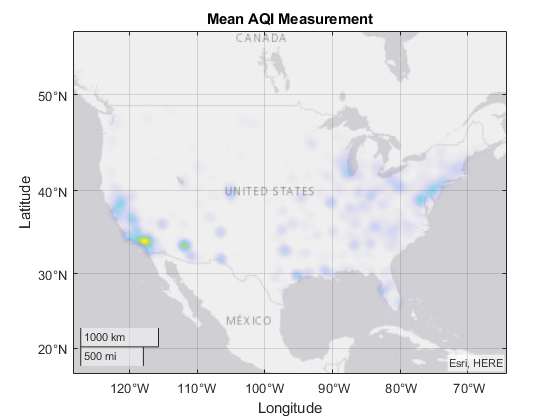

geodensityplot(subset_O.Latitude,subset_O.Longitude,subset_O.AQI,"FaceColor","interp");
title("Mean AQI Measurement")
geolimits([16.4 55.7],[-128.4 -64.2])  % zoom in 

Create a word cloud of the states to see the frequency of the measurements by location in this subset.

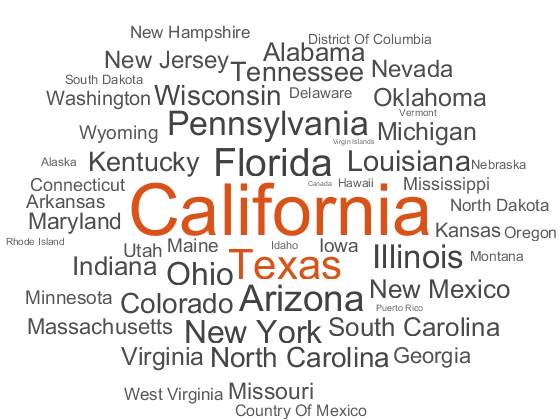

wordcloud(subset_O.StateName);

### Examine locations in larger data set

Since this is a subset of the data, it is difficult to tell if we should group by the state. Examine the distribution of locations in the larger data set. 

You can visualize all data in the `tall` array without reading everything into memory:Use `plot`, `scatter` for time stamped data and `binscatter`, `histogram/histogram2`, `ksdensity`, `pie`, and `wordcloud` for distributions. 

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 2 sec
- Pass 2 of 2: Completed in 1.9 sec
Evaluation completed in 4.5 sec


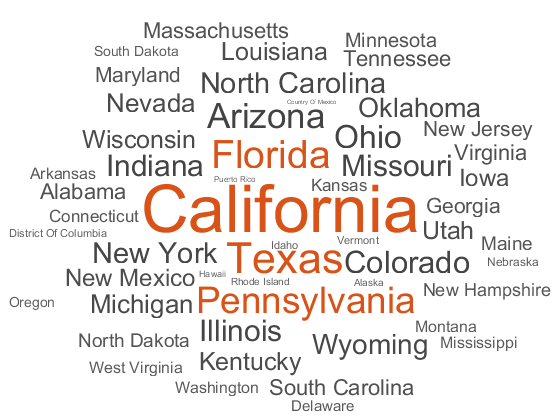

wc = wordcloud(ozone.StateName);

## Preprocess data

Two timetables have multiple measurements in them. We want to separate these by measurement types before synchronizing (since the others are arranged this way). 

varnames = ["StateName","SampleMeasurement"];
WindDir1 = wind1(wind1.ParameterName == "Wind Direction - Resultant",varnames);
WindSpd1 = wind1(wind1.ParameterName == "Wind Speed - Resultant",varnames);
RH1 = rhdp1(rhdp1.ParameterName == "Relative Humidity",varnames);
DP1 = rhdp1(rhdp1.ParameterName == "Dew Point",varnames);

## Synchronize data to daily timestamps by location

Try this first locally on a few of the subsets of data. Use the average measurement to reduce the hourly data. 

statenm = "Alabama";
varname = "SampleMeasurement";
T = temps1(temps1.StateName == statenm,varname);
P = pressure1(pressure1.StateName == statenm,varname);

dailyData = synchronize(T,P,"daily","mean");
head(dailyData)

ans = 8×2 timetable
         DateLocal          SampleMeasurement_T    SampleMeasurement_P
    ____________________    ___________________    ___________________
    01-Jan-2017 00:00:00          58.635                 993.97       
    02-Jan-2017 00:00:00          61.742                 993.42       
    03-Jan-2017 00:00:00          60.373                 989.82       
    04-Jan-2017 00:00:00           45.46                 993.32       
    05-Jan-2017 00:00:00          40.469                 991.51       
    06-Jan-2017 00:00:00          31.138                 995.28       
    07-Jan-2017 00:00:00          27.573                 1001.7       
    08-Jan-2017 00:00:00          29.144                 1010.5       

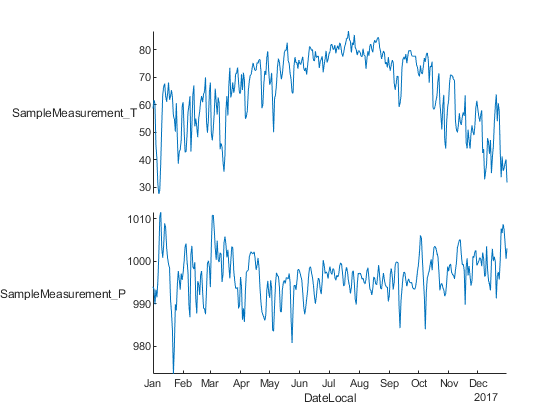

figure
stackedplot(dailyData);

Create a function below to synchronize all measurements and write the data to file by state. (**Note** the `write` function requires the directory to be empty) 

writepath = "localData"+filesep;
states = ["Alabama";"Arizona"];
% synchData(states,temps1,pressure1,wind1,rhdp1,...
%     ozone1,co1,so21,no21,writepath,"mat");

Examine the synchronized values.

load("localData"+filesep+"Alabama"+filesep+"array_r01_00001_snapshot_0x1.mat")
AL = Value{1};
AL.Properties.VariableNames = erase(AL.Properties.VariableNames,["ArithmeticMean_",...
    "SampleMeasurement_"]);
AL = sortrows(AL);
head(AL)

ans = 8×12 timetable
    DateLocal     StateName    AQI       O3         CO         SO2       NO2        T         P       WindDir    WindSpd    DP       RH  
    __________    _________    ___    ________    _______    _______    ______    ______    ______    _______    _______    ___    ______
    2017-01-01     Alabama     13     0.012455    0.48221     1.6833       5.7    58.635    993.97    120.69     1.6625     NaN    95.938
    2017-01-02     Alabama     30     0.024529    0.52554     1.6708    6.3792    61.742 

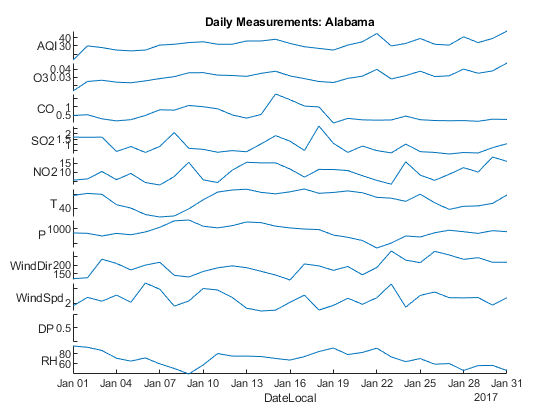

figure
stackedplot(AL(:,2:end));
title("Daily Measurements: "+string(AL.StateName(1)))

## Synchronize and write data for all locations 

Write the data for all states over all years. You can use the same code for the `tall` arrays representing all of the data on HDFS. 

if useSpark
    writepath = "hdfs://hadoop01glnxa64:54310/datasets/AirQuality/preprocessed/";   %#ok
    filetype = "seqn"; %"parquet"
    states = categories(subset_T.StateName);
    % Synchronize and write by state
    synchData(states,temps,pressure,wind,rhdp,...
        ozone,co,so2,no2,writepath,filetype);
end

See the `preprocessedData` directory for the daily averages for all states. 

## Build model on daily data

Now we can analyze the daily data and start building the model. 

edit BuildAirQualityModel.mlx

**Helper functions**

function synchData(states,temps,press,wind,rhdp,...
    ozone,co,so2,no2,writepath,filetype)
% Synchronize chemical and meteorological data to daily timestamps by
% location (US State)

% states is a list of locations (US States)
states = convertCharsToStrings(states);
nstates = length(states);

% identify variables
metvar = "SampleMeasurement";
chemvar = "ArithmeticMean";

for ii = 1:nstates
    % Select data to synchronize by state
    statenm = states(ii);
    
    % Meteorological data
    T = temps(temps.StateName == statenm, metvar);
    P = press(press.StateName == statenm, metvar);
    
    WindDir = wind(wind.StateName == statenm & ...
        wind.ParameterName == "Wind Direction - Resultant", metvar);
    WindSpd = wind(wind.StateName == statenm & ...
        wind.ParameterName == "Wind Speed - Resultant", metvar);
    DP = rhdp(rhdp.StateName == statenm & ...
        rhdp.ParameterName == "Dew Point",metvar);
    RH = rhdp(rhdp.StateName == statenm & ...
        rhdp.ParameterName == "Relative Humidity",metvar);
    
    % Chemical measurements
    O3 = ozone(ozone.StateName == statenm,...
        ["StateName","AQI",chemvar]);
    CO = co(co.StateName == statenm,chemvar);
    SO2 = so2(so2.StateName == statenm,chemvar);
    NO2 = no2(no2.StateName == statenm,chemvar);
    
    % Synchronize all data to daily averages
    dailyMeteorologicalData = synchronize(T,P,WindDir,WindSpd,...
        DP,RH,"daily","mean");
    dailyData = synchronize(O3,CO,SO2,NO2,...
        dailyMeteorologicalData);
    
    % Write the daily data to file
    % Remove spaces in state name
    statenm = erase(statenm," ");
    newfiledir = writepath+statenm;
    % write to file
    if ~istall(dailyData)
        dailyData = tall(dailyData);
    end
    
    write(newfiledir,dailyData,"FileType",filetype)
    
end
end
